# Antenna and Free-Space Propagation In-Class Exercises

These exercises follow the lectures and are to be done at the end of each section.

## Problem 1:  Computing Wavelength and E-Field Amplitude

Suppose that an EM-plane wave has:

- Power flux density is 1 nW/m^2

- Freq = 2.3 GHz

Print the:

- Maximum E-field value assuming a characteristic impedance of eta = `120*pi` ohms

- Wavelength.  You may use the `physconst('Lightspeed')` command to get the speed of light.

Make sure you print the units.

% TODO
P = 1e-9;      % 1 nW/m^2 of power
eta = 120*pi;  % characteristic impedence 

% The power flux is P = E0^2/eta/2.  Note the factor of two!  We can then
% invert this equation:
E0 = sqrt(2*P*eta);
fprintf(1,'E0=%12.4e V/m', E0);

E0=  8.6832e-04 V/m

% For the wavelength, we use lambda = c/f
f = 2.3e9;
c=physconst('Lightspeed');
lambda = c/f;
fprintf(1,'lam=%12.4e m', lambda);

lam=  1.3034e-01 m

## Problem 2:  Computing Power in a LTE PSS

In an LTE system, each base station (called eNB in 3GPP terminology) periodically transmits a Primary Synchronization Signal (PSS) so that mobiles  (called a UEs or user equipments) can detect the base station.  The PSS occupies:

- In frequency:  72 sub-carriers at 15 kHz per sub-carrier

- In time:  One OFDM symbol = 2048 samples at 30.72 Ms/s

The following diagram shows the transmission of the PSS when it is configured to be transmitted every 5ms.  Other synchronization and reference signals are also shown.

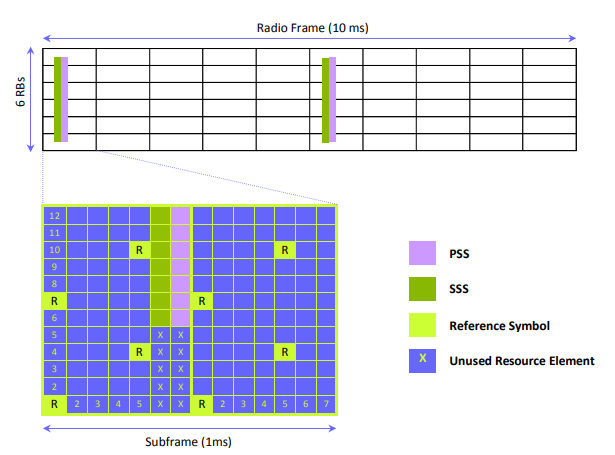

Suppose the eNB has a total transmit power of 43 dBm uniformly over 20 MHz.  The path loss between the eNB and UE is 100 dB.  What is the received energy per PSS?  Print your answer in dBmJ.

% TODO
fsamp = 30.72e6;
Tpss = 2048/fsamp;
bwPss = 72*15e3;  % bandwidth of the PSS in Hz
bwTot = 20e6;     % total BW in Hz
PL = 100;         % path loss in dB

PtxTot = 43;  % Total transmit power
ErxPss = PtxTot + 10*log10(bwPss/bwTot) - PL + 10*log10(Tpss);

fprintf(1,'Erx = %12.4e dBmJ', ErxPss);

Erx =  -1.1144e+02 dBmJ

## Problem 3:  Creating and Displaying a Patch Antenna

Create the 28 GHz patch antenna as follows:

% Compute the wavelength
fc = 28e9;
c=physconst('Lightspeed');
lambda = c/fc;

% Create the patch antenna
len = 0.49*lambda;
groundPlaneLen = lambda;
ant = patchMicrostrip(...
    'Length', len, 'Width', 1.5*len, ...
    'GroundPlaneLength', groundPlaneLen, ...
    'GroundPlaneWidth', groundPlaneLen, ...
    'Height', 0.01*lambda, ...
    'FeedOffset', [0.25*len 0]);

Use the `ant.show()` command to display the antenna.

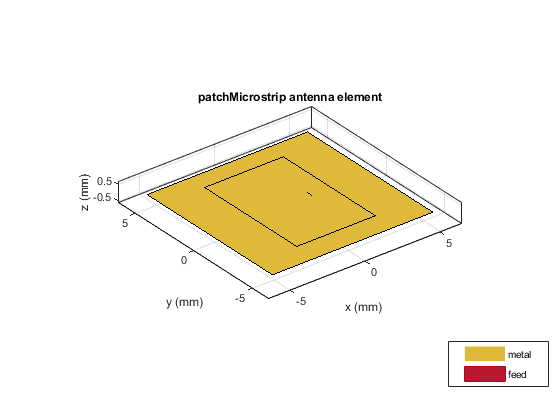

Z = 13.9935 - 13.9651i

% TODO
ant.show()

Now suppose the TX is at the origin and we have a RX target at the following position:

rxPos = [1000,500,100];

Find the azimuth and elevation angle and distance to the RX.  Use the `car2sph` and `rad2deg` commands:

% TODO
%  az0 = ...
%  el0 = ...
%  rad0 + ...
[az0, el0, rad0] = cart2sph(rxPos(1), rxPos(2), rxPos(3));
az0 = rad2deg(az0);
el0 = rad2deg(el0);

fprintf(1, 'az=%f el=%f\n', az0, el0);

az=26.565051 el=5.111090


Now rotate the antenna to point towards the target.  You can do this with the code:

where y`Rot` and `zRot` are the angles to rotate the element in the y and z axes.  Select `yRot` and `zRot, run the` command to point to the target and display the antenna.  You may want to use the `view([...])` command to select a good view point so you can see the front of the antenna.

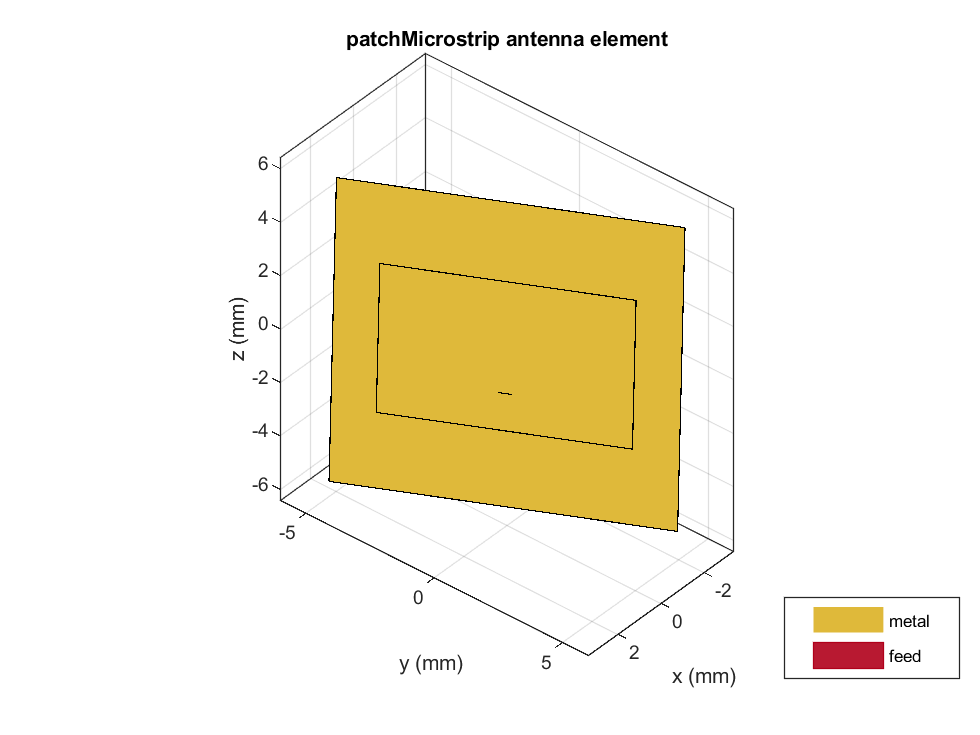

% TODO
%   yRot = ...
%   zRot = ...
yRot = 90-el0;  % Rotate in the y axis by the inclination angle
zRot = az0;     % Rotate in the z axis by the azimuth
ant.set('Tilt',[yRot, zRot], 'TiltAxis', [0 1 0; 0 0 1]);
ant.show();
view([130 37]);

## Problem 4:  Plotting the Far Field Radiation Pattern

Use the `ant.pattern` command to get the pattern of the rotated antenna.  

% TODO:
%    [dir, az, el] = ant.pattern(...)

% You can also save the pattern c
[dir,az,el] = ant.pattern(fc, 'Type', 'Directivity');

Use the `imagesc` command to plot the antenna pattern as a function of the azimuth and elevation angles.  Add a colorbar, label the axes.  Place a marker at the location `[az0, el0],` the desired direction. 

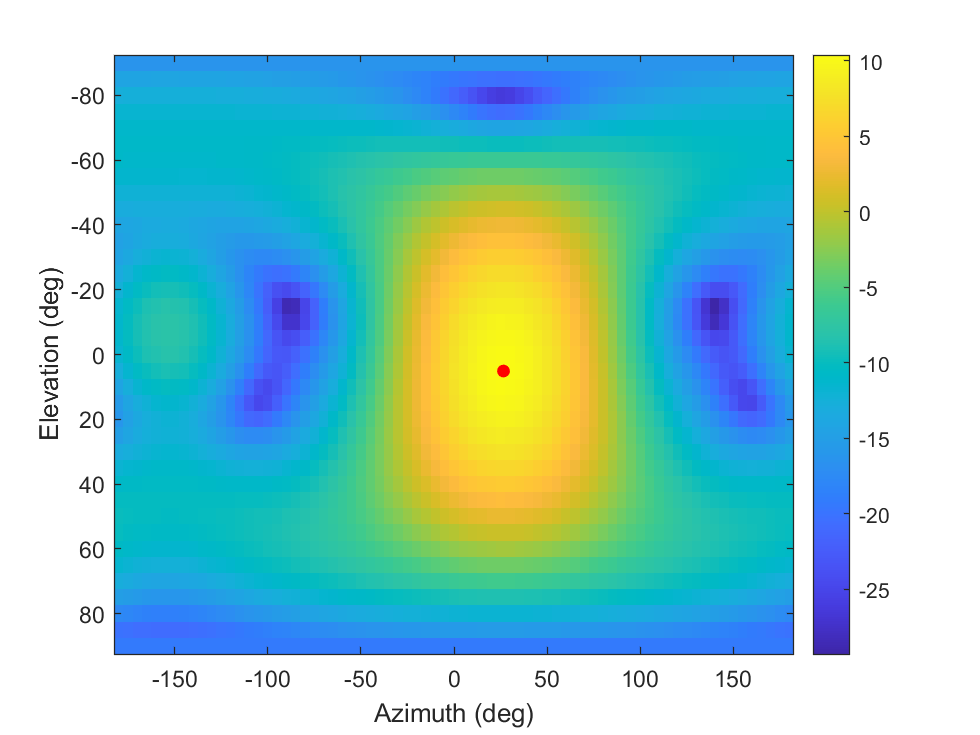

% TODO
% Plot the directivity
imagesc(az,el,dir);
colorbar();
xlabel('Azimuth (deg)');
ylabel('Elevation (deg)');
hold on;

% Add a marker on the desired target
plot(az0, el0, 'ro', 'MarkerSize', 5, 'MarkerFaceColor', 'r');
Chold off;

Use the `griddedInterpolant` object with the directivity data.  Then use the gridded interpolant to find the directivity to the target at `[az0, el0]`.

% TODO
%    F = griddedInterpolant(...)
%    dir0 = ...
F = griddedInterpolant({el,az},dir);

% Then, we compute the directivity using the object
dir0 = F(el0,az0);

Compute the free space path loss including the TX directivity to the target.

% TODO
plOmni = fspl(rad0, lambda);
plDir = plOmni - dir0;
fprintf(1, 'Omni PL = %12.4e\n', plOmni);

Omni PL =   1.2239e+02


fprintf(1, 'PL with directivity = %12.4e\n', plDir);

PL with directivity =   1.1203e+02
